%% NMR Titration Fit: 1:2 Host-Guest + Guest Dimerization
clear; clc;

%% === INPUT DATA ===
% Total host and guest concentrations (in mol/L)
Htot = [1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1]' * 1e-3; % e.g., 1 mM constant
Gtot = linspace(0.1, 5, 20)' * 1e-3; % from 0.1 to 5 mM

% Experimental chemical shifts (ppm) — replace with your real data
delta_obs_exp = [8.00, 7.80, 7.60, 7.40, 7.30, 7.20, 7.15, 7.10, 7.05, 7.00, ...
                 6.98, 6.95, 6.92, 6.90, 6.88, 6.86, 6.85, 6.84, 6.83, 6.82]';

% Known guest dimerization constant (M⁻¹)
Kdimer = 15.1;

%% === Fit Parameters ===
% Initial guess: [logK1, logK2, δ_free, δ_HG, δ_HG2]
params0 = [4, 3, 8.0, 6.5, 4.5];
lb = [1, 1, -Inf, -Inf, -Inf];
ub = [10, 10, Inf, Inf, Inf];

options = optimoptions('lsqcurvefit','Display','iter','TolFun',1e-9);

%% === Fit Model ===
[params_fit,~,residual,~,~,~,J] = lsqcurvefit(@(p,x) model(p,x,Kdimer), ...
    params0, [Htot Gtot], delta_obs_exp, lb, ub, options);


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          6           35.2163                             40.3
     1         12        0.00562001         2.30752           0.0277      
     2         18        0.00562001        0.488081           0.0277      
     3         24        0.00461662         0.12202           0.0834      
     4         30        0.00266185         0.12202            0.248      
     5         36        0.00142897        0.115956              0.1      
     6         42        0.00110669        0.103503           0.0435      
     7         48        0.00100991        0.110396           0.0317      
     8         54       0.000947872       0.0672005          0.00712      
     9         60       0.000942888        0.034938          0.00141      
    10         66       0.000942705      0.00467223         1.64e-05      
    11         72       0.000942705     6


% Get fit results
delta_fit = model(params_fit, [Htot Gtot], Kdimer);

% Calculate confidence intervals (optional)
ci = nlparci(params_fit,residual,'jacobian',J);

% Print fitted values
fprintf('\nFitted Parameters:\n');


Fitted Parameters:


fprintf('K1      = %.2e (%.2e - %.2e)\n', 10^params_fit(1), 10^ci(1,1), 10^ci(1,2));

K1      = 1.86e+05 (1.43e+04 - 2.42e+06)


fprintf('K2      = %.2e (%.2e - %.2e)\n', 10^params_fit(2), 10^ci(2,1), 10^ci(2,2));

K2      = 7.12e+02 (4.99e+02 - 1.02e+03)


fprintf('δ_free  = %.2f\n', params_fit(3));

δ_free  = 8.07


fprintf('δ_HG    = %.2f\n', params_fit(4));

δ_HG    = 7.30


fprintf('δ_HG2   = %.2f\n', params_fit(5));

δ_HG2   = 6.59


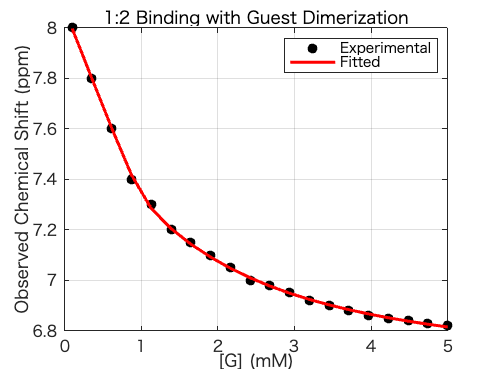


%% === Plot Results ===
figure;
plot(Gtot*1e3, delta_obs_exp, 'ko', 'MarkerFaceColor', 'k'); hold on;
plot(Gtot*1e3, delta_fit, 'r-', 'LineWidth', 2);
xlabel('[G] (mM)');
ylabel('Observed Chemical Shift (ppm)');
legend('Experimental', 'Fitted');
title('1:2 Binding with Guest Dimerization');
grid on;


%% === Output Table of Species and Shifts ===
% Calculate concentrations of species
N = length(Gtot);
species_table = table('Size', [N 7], ...
    'VariableTypes', repmat({'double'}, 1, 7), ...
    'VariableNames', {'Htot_mM', 'Gtot_mM', '[HG]_uM', '[HG2]_uM', '[G2]_uM', 'δ_obs', 'δ_fit'});

for i = 1:N
    Ht = Htot(i); Gt = Gtot(i);
    x0 = [Gt/2, 1e-6, 1e-6, 1e-6]; % [G, HG, HG2, G2]
    sol = fsolve(@(x) equations(x, Gt, Ht, 10^params_fit(1), 10^params_fit(2), Kdimer), x0, ...
        optimoptions('fsolve','Display','off'));

    G = sol(1); HG = sol(2); HG2 = sol(3); G2 = sol(4);
    H_free = Ht - HG - HG2;
    Del_fit = (H_free * params_fit(3) + HG * params_fit(4) + HG2 * params_fit(5)) / Ht;

    species_table{i,:} = [Ht*1e3, Gt*1e3, HG*1e6, HG2*1e6, G2*1e6, delta_obs_exp(i), Del_fit];
end

disp('Concentration Table (μM, mM, ppm):');

Concentration Table (μM, mM, ppm):


disp(species_table);

    Htot_mM    Gtot_mM    [HG]_uM    [HG2]_uM     [G2]_uM      δ_obs    δ_fit 
    _______    _______    _______    ________    __________    _____    ______

       1           0.1    99.322     0.041984     5.294e-06       8     7.9972
       1       0.35789    353.47       0.7415    0.00013099     7.8     7.7988
       1       0.61579    600.64       3.4928      0.001007     7.6     7.6027
       1       0.87368    816.96       15.246      0.010371     7.4     7.4173
       1        1.1316    887.59       68.014       0.17486     7.3     7.2841
       1        1.3895    831.72       150.69       0.97747     7.2     7.2049
       1        1.6474    761.23       229.07        2.6967    7.15     7.1433
       1        1.9053    695.51       298.27        5.4769     7.1     7.0917
       1        2.1632    637.16        358.5        9.4274    7.05     7.0476
       1        2.4211    586.05       410.75        14.628       7     7.0098
       1        2.6789    541.43       456.11      


% Calculate R-squared
SS_res = sum((delta_obs_exp - delta_fit).^2);
SS_tot = sum((delta_obs_exp - mean(delta_obs_exp)).^2);
R_squared = 1 - (SS_res / SS_tot);

% Display R-squared
fprintf('R-squared: %.4f\n', R_squared);

R-squared: 0.9996



function delta_obs = model(params, xdata, Kdimer)
    K1 = 10^params(1); K2 = 10^params(2);
    delta_free = params(3); delta_HG = params(4); delta_HG2 = params(5);

    Htot = xdata(:,1);
    Gtot = xdata(:,2);
    N = length(Htot);
    delta_obs = zeros(N,1);

    for i = 1:N
        x0 = [Gtot(i)/2, 1e-6, 1e-6, 1e-6];
        sol = fsolve(@(x) equations(x, Gtot(i), Htot(i), K1, K2, Kdimer), x0, ...
            optimoptions('fsolve','Display','off'));
        G = sol(1); HG = sol(2); HG2 = sol(3);
        H_free = Htot(i) - HG - HG2;
        delta_obs(i) = (H_free * delta_free + HG * delta_HG + HG2 * delta_HG2) / Htot(i);
    end
end

function F = equations(x, Gtot, Htot, K1, K2, Kdimer)
    G = x(1); HG = x(2); HG2 = x(3); G2 = x(4);
    H = Htot - HG - HG2;
    F(1) = HG - K1 * H * G;
    F(2) = HG2 - K2 * HG * G;
    F(3) = G2 - Kdimer * G^2;
    F(4) = Gtot - (G + HG + 2*HG2 + 2*G2);
end
